%zad3
O1=rgb2gray(imread("1.png"));
O2=rgb2gray(imread("2.png"));
O3=rgb2gray(imread("4.png"));
O4=rgb2gray(imread("5.png"));
% %szumienie
filtracja='medianowej';
sO1 = imnoise(O1,'salt & pepper',0.1);
sO2 = imnoise(O2,'salt & pepper',0.1);
sO3 = imnoise(O3,'salt & pepper',0.1);
sO4 = imnoise(O4,'salt & pepper',0.1);
%filtracja

filtracja = 'medianowej'

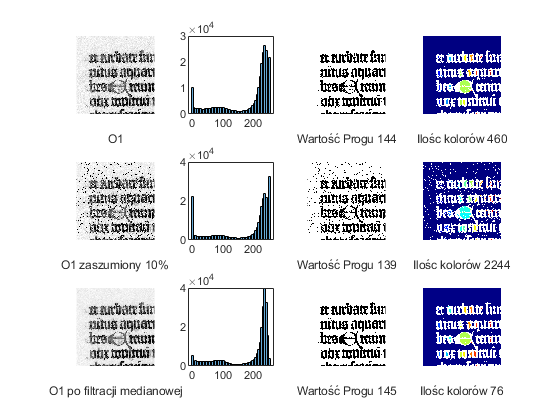

fO1=mediana(sO1,3);
fO2=mediana(sO2,3);
fO3=mediana(sO3,3);
fO4=mediana(sO4,3);
%szumienie gaussowe
% filtracja='średniej';
% sO1 = imnoise(O1,'gaussian',0.05);
% sO2 = imnoise(O2,'gaussian',0.05);
% sO3 = imnoise(O3,'gaussian',0.05);
% sO4 = imnoise(O4,'gaussian',0.05);
% F=fspecial('average',7);
% fO1=imfilter(sO1,F);
% fO2=imfilter(sO2,F);
% fO3=imfilter(sO3,F);
% fO4=imfilter(sO4,F);
%otsu dla normalnych
O1op=graythresh(O1)*255;
O2op=graythresh(O2)*255;
O3op=graythresh(O3)*255;
O4op=graythresh(O4)*255;
%binarka dla normalnych
O1obin=binarka(O1,O1op);
O2obin=binarka(O2,O2op);
O3obin=binarka(O3,O3op);
O4obin=binarka(O4,O4op);
%kolory dla normalnych
pseudoO1o=bwlabel(O1obin);
pseudoO2o=bwlabel(O2obin);
pseudoO3o=bwlabel(O3obin);
pseudoO4o=bwlabel(O4obin);
sk1=max(unique(pseudoO1o))+1;
sk2=max(unique(pseudoO2o))+1;
sk3=max(unique(pseudoO3o))+1;
sk4=max(unique(pseudoO4o))+1;
pseudoO1o=label2rgb(pseudoO1o);
pseudoO2o=label2rgb(pseudoO2o);
pseudoO3o=label2rgb(pseudoO3o);
pseudoO4o=label2rgb(pseudoO4o);
%otsu dla szumu
sO1op=graythresh(sO1)*255;
sO2op=graythresh(sO2)*255;
sO3op=graythresh(sO3)*255;
sO4op=graythresh(sO4)*255;
%binarka dla szumu
sO1obin=binarka(sO1,sO1op);
sO2obin=binarka(sO2,sO2op);
sO3obin=binarka(sO3,sO3op);
sO4obin=binarka(sO4,sO4op);
%kolory dla normalnych
spseudoO1o=bwlabel(sO1obin);
spseudoO2o=bwlabel(sO2obin);
spseudoO3o=bwlabel(sO3obin);
spseudoO4o=bwlabel(sO4obin);
ssk1=max(unique(spseudoO1o))+1;
ssk2=max(unique(spseudoO2o))+1;
ssk3=max(unique(spseudoO3o))+1;
ssk4=max(unique(spseudoO4o))+1;
spseudoO1o=label2rgb(spseudoO1o);
spseudoO2o=label2rgb(spseudoO2o);
spseudoO3o=label2rgb(spseudoO3o);
spseudoO4o=label2rgb(spseudoO4o);
%otsu dla filtracji
fO1op=graythresh(fO1)*255;
fO2op=graythresh(fO2)*255;
fO3op=graythresh(fO3)*255;
fO4op=graythresh(fO4)*255;
%binarka dla filtracji
fO1obin=binarka(fO1,fO1op);
fO2obin=binarka(fO2,fO2op);
fO3obin=binarka(fO3,fO3op);
fO4obin=binarka(fO4,fO4op);
%kolory dla filtracji
fpseudoO1o=bwlabel(fO1obin);
fpseudoO2o=bwlabel(fO2obin);
fpseudoO3o=bwlabel(fO3obin);
fpseudoO4o=bwlabel(fO4obin);
fsk1=max(unique(fpseudoO1o))+1;
fsk2=max(unique(fpseudoO2o))+1;
fsk3=max(unique(fpseudoO3o))+1;
fsk4=max(unique(fpseudoO4o))+1;
fpseudoO1o=label2rgb(fpseudoO1o);
fpseudoO2o=label2rgb(fpseudoO2o);
fpseudoO3o=label2rgb(fpseudoO3o);
fpseudoO4o=label2rgb(fpseudoO4o);


A=figure();
subplot(3,4,1);
imshow(O1);
xlabel("O1")
subplot(3,4,2);
histogram(O1);
subplot(3,4,3);
imshow(O1obin)
xlabel("Wartość Progu "+O1op)
subplot(3,4,4);
imshow(pseudoO1o)
xlabel("Ilośc kolorów " +sk1)
subplot(3,4,5);
imshow(sO1);
xlabel("O1 zaszumiony 10% ")
subplot(3,4,6);
histogram(sO1);
subplot(3,4,7);
imshow(sO1obin)
xlabel("Wartość Progu "+sO1op)
subplot(3,4,8);
imshow(spseudoO1o);
xlabel("Ilośc kolorów " +ssk1)
subplot(3,4,9);
imshow(fO1);
xlabel("O1 po filtracji "+ filtracja)
subplot(3,4,10);
histogram(fO1);
subplot(3,4,11);
imshow(fO1obin)
xlabel("Wartość Progu "+fO1op)
subplot(3,4,12);
imshow(fpseudoO1o);
xlabel("Ilośc kolorów " +fsk1)

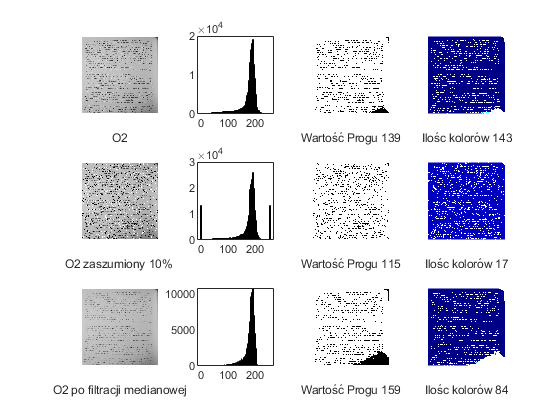


B=figure();
subplot(3,4,1);
imshow(O2);
xlabel("O2")
subplot(3,4,2);
histogram(O2);
subplot(3,4,3);
imshow(O2obin)
xlabel("Wartość Progu "+O2op)
subplot(3,4,4);
imshow(pseudoO2o)
xlabel("Ilośc kolorów " +sk2)
subplot(3,4,5);
imshow(sO2);
xlabel("O2 zaszumiony 10% ")
subplot(3,4,6);
histogram(sO2);
subplot(3,4,7);
imshow(sO2obin)
xlabel("Wartość Progu "+sO2op)
subplot(3,4,8);
imshow(spseudoO2o);
xlabel("Ilośc kolorów " +ssk2)
subplot(3,4,9);
imshow(fO2);
xlabel("O2 po filtracji "+ filtracja)
subplot(3,4,10);
histogram(fO2);
subplot(3,4,11);
imshow(fO2obin)
xlabel("Wartość Progu "+fO2op)
subplot(3,4,12);
imshow(fpseudoO2o);
xlabel("Ilośc kolorów " +fsk2)

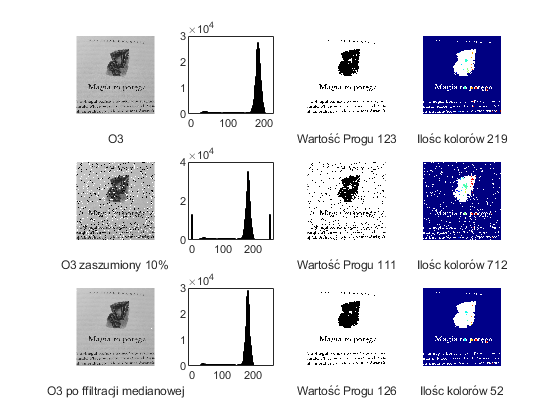


C=figure();
subplot(3,4,1);
imshow(O3);
xlabel("O3")
subplot(3,4,2);
histogram(O3);
subplot(3,4,3);
imshow(O3obin)
xlabel("Wartość Progu "+O3op)
subplot(3,4,4);
imshow(pseudoO3o)
xlabel("Ilośc kolorów " +sk3)
subplot(3,4,5);
imshow(sO3);
xlabel("O3 zaszumiony 10% ")
subplot(3,4,6);
histogram(sO3);
subplot(3,4,7);
imshow(sO3obin)
xlabel("Wartość Progu "+sO3op)
subplot(3,4,8);
imshow(spseudoO3o);
xlabel("Ilośc kolorów " +ssk3)
subplot(3,4,9);
imshow(fO3);
xlabel("O3 po ffiltracji "+ filtracja)
subplot(3,4,10);
histogram(fO3);
subplot(3,4,11);
imshow(fO3obin)
xlabel("Wartość Progu "+fO3op)
subplot(3,4,12);
imshow(fpseudoO3o);
xlabel("Ilośc kolorów " +fsk3)

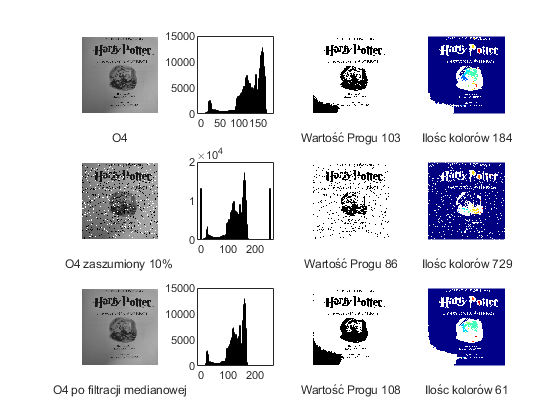


D=figure();
subplot(3,4,1);
imshow(O4);
xlabel("O4")
subplot(3,4,2);
histogram(O4);
subplot(3,4,3);
imshow(O4obin)
xlabel("Wartość Progu "+O4op)
subplot(3,4,4);
imshow(pseudoO4o)
xlabel("Ilośc kolorów " +sk4)
subplot(3,4,5);
imshow(sO4);
xlabel("O4 zaszumiony 10% ")
subplot(3,4,6);
histogram(sO4);
subplot(3,4,7);
imshow(sO4obin)
xlabel("Wartość Progu "+sO4op)
subplot(3,4,8);
imshow(spseudoO4o);
xlabel("Ilośc kolorów " +ssk4)
subplot(3,4,9);
imshow(fO4);
xlabel("O4 po filtracji "+ filtracja)
subplot(3,4,10);
histogram(fO4);
subplot(3,4,11);
imshow(fO4obin)
xlabel("Wartość Progu "+fO4op)
subplot(3,4,12);
imshow(fpseudoO4o);
xlabel("Ilośc kolorów " +fsk4)